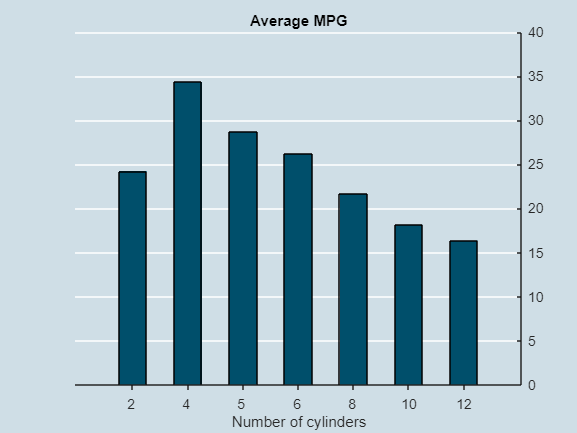

dat = datastore("fuelEconomy2.txt");
dat.ReadSize = 362;
data = dat.read;
[gNum,gVal] = findgroups(data.NumCyl);
avgMPG = splitapply(@mean,data.CombinedMPG,gNum);
b = bar(avgMPG);
xlabel("Number of cylinders")
title("Average MPG")
f = gcf;
a = gca;
f.Color = [0.81 0.87 0.9];
a.Color = [0.81 0.87 0.9];
a.Box = "off";
a.YAxisLocation = "right";
a.YGrid = "on";
a.GridColor = [1 1 1];
a.GridAlpha = 1;
a.XTickLabel = gVal;
a.YLim = [0 40];
ax = a.XAxis;
ax.TickDirection = "out";
b.FaceColor = [0,0.31,0.42];
b.BarWidth = 0.5;